A4.3（`哪类标量循环应被数组运算替代`）实时脚本

由张志涌编写、修改于 2023.1。

a=1;b=3;					%
x=-a:0.1:a;y=-b:0.2:b;		%
Z1=exmA4_11(x,y);			%
Z2=exmA4_12(x,y);			%
E12=max(abs(Z1(:)-Z2(:)))	%

E12 = 0

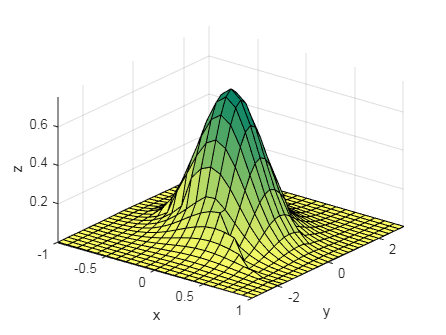

clf								%
surf(x,y,Z2)					%
view([38,32])					%
xlabel('x'),ylabel('y'),zlabel('z')			
axis([-a,a,-b,b,min(min(Z1)),max(max(Z1))])
colormap(flipud(summer))

set(gcf,'Color','white')

function Z=exmA4_11(x,y)
M=length(x);
N=length(y);
Z=zeros(N,M);
for jj=1:M
    for ii=1:N
        if x(jj)+y(ii)<=-1
        Z(ii,jj)=0.546*exp(...
        -0.75*y(ii)^2-3.75*x(jj)^2+1.5*x(jj));
        elseif -1<x(jj)+y(ii)&&x(jj)+y(ii)<=1
        Z(ii,jj)=0.758*exp(-y(ii)^2-6*x(jj)^2);
        else
        Z(ii,jj)=0.546*exp(...
        -0.75*y(ii)^2-3.75*x(jj)^2-1.5*x(jj));
        end
    end
end
end
function Z=exmA4_12(x,y)
    [X,Y]=meshgrid(x,y);
    L1=X+Y<=1;			
    L2=-1<X+Y&X+Y<=1;	
    L3=1<X+Y;			
    Z=zeros(size(X));	
    Z(L1)=0.546*exp(-0.75*Y(L1).^2-3.75*X(L1).^2+1.5*X(L1));
    Z(L2)=0.758*exp(-Y(L2).^2-6*X(L2).^2);
    Z(L3)=0.546*exp(-0.75*Y(L3).^2-3.75*X(L3).^2-1.5*X(L3));
end

